# 3.1.3

% Define our function
f = @(t) exp(sin(t-1));
t = linspace(0,2*pi,200)';

## (a) Polynomial Interpolant

% Setup interpolation matrix
Aa = (t.^(0:7));
b = f(t);

% Solve for polynomial coefficients
xa = Aa\b

xa =     0.3263
    1.6443
   -3.8803
    4.7017
   -2.3206
    0.5403
   -0.0601
    0.0026


## (b) Trig Interpolant

% Setup interpolation matrix
Ab = [ones(length(t),1), cos(t), sin(t), cos(2*t), sin(2*t)];
b = f(t);

% Solve for trig coefficients
xb = Ab\b

xb =     1.2661
   -0.9511
    0.6107
    0.1130
   -0.2469


## (c)

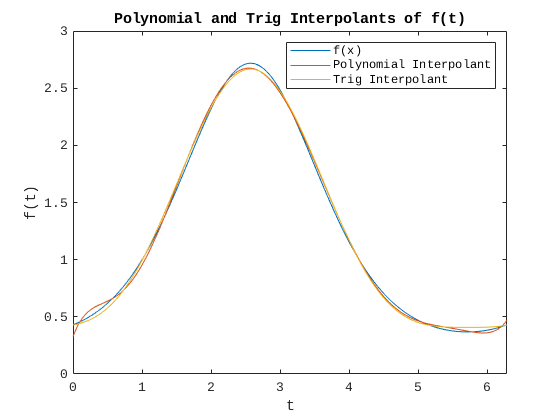

figure()
plot(t,f(t))
hold on
plot(t, Aa*xa)
plot(t,Ab*xb)
title('Polynomial and Trig Interpolants of f(t)')
xlabel('t')
ylabel('f(t)')
xlim([0,2*pi])
legend('f(x)','Polynomial Interpolant','Trig Interpolant')

Both interpolants do a decent job of resolving our function. The left boundary is more accurate in the trig interpolant than the polynomial interpolant. 

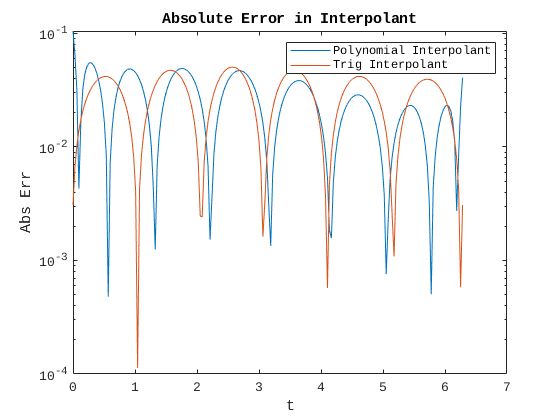

figure()
errsa = abs(Aa*xa - f(t));
errsb = abs(Ab*xb - f(t));
semilogy(t,errsa,t,errsb)
title('Absolute Error in Interpolant')
xlabel('t')
ylabel('Abs Err')
legend('Polynomial Interpolant','Trig Interpolant')

Our error plot shows that each interpolant periodically over estimates and then underestimates our function. The trig interpolant is more consistent in the error bounds than the polynomial interpolant. But, the polynomial interpolant does approximate the right boundary better. The better approximation could be for a number of reason. The largest factor is most likely due to there being more terms in the polynomial interpolant than the trig interpolant.

# 3.2.4

If $A$ is nonsingular, then $A^+ = A^{-1}$

*Proof:*

First not that if $A$ is nonsingular, then it is invertible and so is its transpose. Then


$$A^+ = (A^T A)^{-1} A^T$$



$$=A^{-1} (A^T)^{-1} A^T$$



$$= A^{-1} I$$


$=A^{-1}$.

Therefore $A^+ = A^{-1}$ for nonsingular matrices $A$.